# Question-01

A1=[-0.8 0.04 -0.88 0; 0 -0.18 0.035 -0.81; 1 -0.2 -0.6 0; 1 0 0 0];
B1=[0 -1.193; 225 0; 0 -0.035; 0 0];
C1=eye(4);
D1=zeros(4,2);

%[b,a] = ss2tf(A1,B1,C1,D1,1)
fprintf('input : 1-δth, 2-δe')

input : 1-δth, 2-δe

fprintf('States/Output : 1-q, 2-u_sp, 3-α, 4-θ')

States/Output : 1-q, 2-u_sp, 3-α, 4-θ


m = ss(A1,B1,C1,D1);
sys = tf(m)

sys =
 
  From input 1 to output...
                       9 s^2 + 45 s
   1:  ---------------------------------------------
       s^4 + 1.58 s^3 + 1.619 s^2 + 0.2814 s + 0.162
 
                 225 s^3 + 315 s^2 + 306 s
   2:  ---------------------------------------------
       s^4 + 1.58 s^3 + 1.619 s^2 + 0.2814 s + 0.162
 
                      -45 s^2 - 27 s
   3:  ---------------------------------------------
       s^4 + 1.58 s^3 + 1.619 s^2 + 0.2814 s + 0.162
 
                         9 s + 45
   4:  ---------------------------------------------
       s^4 + 1.58 s^3 + 1.619 s^2 + 0.2814 s + 0.162
 
  From input 2 to output...
       -1.193 s^3 - 0.8997 s^2 - 0.1317 s - 2.697e-35
   1:  ----------------------------------------------
       s^4 + 1.58 s^3 + 1.619 s^2 + 0.2814 s + 0.162
 
             -0.001225 s^2 + 0.9236 s + 0.5548
   2:  ---------------------------------------------
       s^4 + 1.58 s^3 + 1.619 s^2 + 0.2814 s + 0.162
 
        -0.035 s^3 - 1.227 s^2 - 0.2


%sys = tf (b,a,'InputName', 'δth', 'δe', 'OutputName', {'q','u','a','t'})

## Question-02

A2=[-0.05 -0.003 -0.98 0.2; -1 -0.75 1 0; 0.3 -0.3 -0.15 0; 0 1 0 0];
B2=[0 0; 1.7 -0.2; 0.3 -0.6; 0 0];
C2=eye(4);
D2=zeros(4,2);

## Question-02 (a)

t = 0:0.01:20;
[y,x,t] = step(A2,B2,C2,D2,1,t);
plot(t,x)

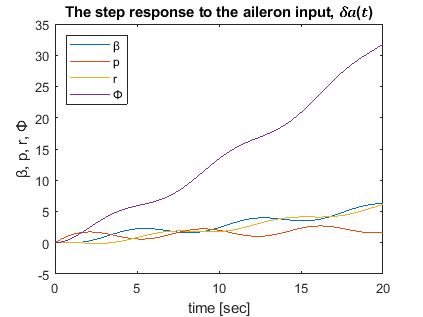

legend({'β','p','r','Φ'},'Location','northwest')
title('The step response to the aileron input, 𝛿𝑎(𝑡)')
xlabel('time [sec]')
ylabel('β, p, r, Φ')

## Question-02 (b)

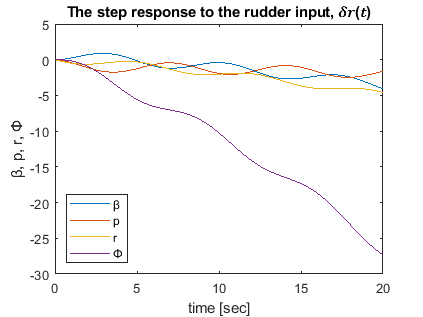

[y,x,t] = step(A2,B2,C2,D2,2,t);
plot(t,x)
legend({'β','p','r','Φ'},'Location','southwest')
title('The step response to the rudder input, 𝛿𝑟(𝑡)')
xlabel('time [sec]')
ylabel('β, p, r, Φ')

## Question-02 (c)

Co = ctrb(A2,B2);
P=rank(Co);
if P==4
    fprintf('The system is completely controllable using both the inputs.')
else
    fprintf('The system is not completely controllable using both the inputs.')
end

The system is completely controllable using both the inputs.

## Question-02 (d)

B2=[0 0; 1.7 0; 0.3 0; 0 0];
Co = ctrb(A2,B2);
P=rank(Co);
if P==4
    fprintf('The aircraft is controllable using only the aileron inputs, 𝛿𝑎.')
else
    fprintf('The aircraft is not controllable using only the aileron inputs, 𝛿𝑎.')
end

The aircraft is controllable using only the aileron inputs, 𝛿𝑎.

## Question-02 (e)

B2=[0 0; 0 -0.2; 0 -0.6; 0 0];
Co = ctrb(A2,B2);
P=rank(Co);
if P==4
    fprintf('The aircraft is controllable using only the rudder input, 𝛿𝑟.')
else
    fprintf('The aircraft is not controllable using only the rudder input, 𝛿𝑟.')
end

The aircraft is controllable using only the rudder input, 𝛿𝑟.

## Question-02 (f)

C2=[0 0 0 0; 0 0 0 0; 0 0 0 0; 0 0 0 1];
Ob = obsv(A2,C2);
P=rank(Ob);
if P==4
    fprintf('The aircraft is observable with the bank-angle, 𝜙(𝑡), being the only measured output.')
else
    fprintf('The aircraft is not observable with the bank-angle, 𝜙(𝑡), being the only measured output.')
end

The aircraft is observable with the bank-angle, 𝜙(𝑡), being the only measured output.

## Question-02 (g)

C2=[1 0 0 0; 0 0 0 0; 0 0 0 0; 0 0 0 0];
Ob = obsv(A2,C2);
P=rank(Ob);
if P==4
    fprintf('The aircraft is observable with the sideslip-angle, 𝛽(𝑡), being the only measured output.')
else
    fprintf('The aircraft is not observable with the sideslip-angle, 𝛽(𝑡), being the only measured output.')
end

The aircraft is observable with the sideslip-angle, 𝛽(𝑡), being the only measured output.

## Question-02 (h)

dp = [-1.5 0.05 -0.35+j*(1.5) -0.35-j*(1.5)];
K = place(A2,B2,dp)

K =          0         0         0         0
   -1.0714   -4.9045   -0.3652    0.4882


## Question-02 (i)

% *** Taking only aileron input ***
r=1;                             % for step response
B2=[0 0; 1.7 0; 0.3 0; 0 0];
dp = [-1+j*1 -1-j*1 -15 -0.8];
K1 = place(A2,B2,dp);
AUG_2_i1 = A2 - B2*K1;

Co = ctrb(AUG_2_i1,B2);
P=rank(Co);
if P==4
    fprintf('The system is controllable using only the aileron input, 𝛿𝑎(𝑡), we can design a full-state feedback control.')
else
    fprintf('The system is not controllable using only the aileron input, 𝛿𝑎(𝑡), we can design a full-state feedback control.')
end

The system is controllable using only the aileron input, 𝛿𝑎(𝑡), we can design a full-state feedback control.


fprintf('Control gain matrix using only the aileron input:\n')

Control gain matrix using only the aileron input:


Gm = K1   % gain matrix K

Gm =    43.7313   12.8379  -16.5816   26.6107
         0         0         0         0




% *** Taking only rudder input ***
r=1;                            % for step response
B2=[0 0; 0 -0.2; 0 -0.6; 0 0];
dp = [-1+j*1 -1-j*1 -15 -0.8];
K2 = place(A2,B2,dp);
AUG_2_i2 = A2 - B2*K2;

Co = ctrb(AUG_2_i2,B2);
P=rank(Co);
if P==4
    fprintf('The system is completely controllable, we can design a full-state feedback control.')
else
    fprintf('The system is not completely controllable, we can not design a full-state feedback control.')
end

The system is completely controllable, we can design a full-state feedback control.


fprintf('Control gain matrix using only the rudder input:\n')

Control gain matrix using only the rudder input:


Gm = K2   % gain matrix K

Gm =          0         0         0         0
    6.0592  -45.3680  -12.9607  -34.0302


## Question-02 (j)

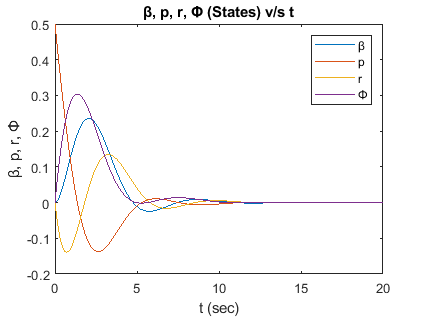

sys = ss(A2,B2,C2,D2);
Q2 = eye(4);
R2 = eye(1);

[Kn,S,P] = lqr(sys,Q2,R2);

t = 0:0.1:20;

AUG_j = A2 - B2*Kn;

sys = ss(AUG_j,eye(4),eye(4),eye(4));
v = [0; 0.5; 0; 0];
x=initial(sys,v,t);

x1 = [1 0 0 0]*x';
x2 = [0 1 0 0]*x';
x3 = [0 0 1 0]*x';
x4 = [0 0 0 1]*x';

plot(t,x1)
hold on
plot(t,x2)
hold on
plot(t,x3)
hold on
plot(t,x4)
hold off
title('β, p, r, Φ (States) v/s t')
xlabel('t (sec)')
ylabel('β, p, r, Φ')
legend('β','p','r','Φ')

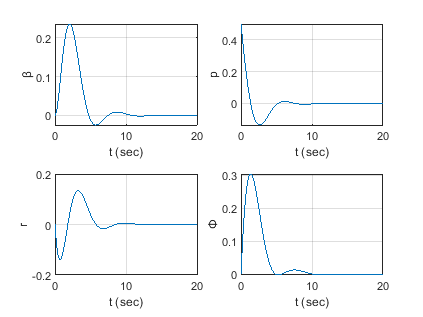


subplot(2,2,1); plot(t,x1); grid
xlabel('t (sec)')
ylabel('β')

subplot(2,2,2); plot(t,x2); grid
xlabel('t (sec)')
ylabel('p')

subplot(2,2,3); plot(t,x3); grid
xlabel('t (sec)')
ylabel('r')

subplot(2,2,4); plot(t,x4); grid
xlabel('t (sec)')
ylabel('Φ')

## Question-03

A3=[0 1 0 0; 0 0 -1 0; 0 0 0 1; 0 0 11 0];
B3=[0; 1; 0; -1];
C3=[1 0 0 0];
D3=[0];

## Question-03 (a)

Q3 = 2*eye(4);
R3 = eye(1);
[K3,S3,P3] = lqr(A3,B3,Q3,R3);
fprintf('Dominant eigenvalue:')

Dominant eigenvalue:

eig(A3-B3*K3)

ans =   -4.1425 + 0.0000i
  -2.6871 + 0.0000i
  -1.0198 + 0.4800i
  -1.0198 - 0.4800i


## Question-03 (b)

% *** First solve pole-placement problem ***
Ob = obsv(A3,C3)

Ob =      1     0     0     0
     0     1     0     0
     0     0    -1     0
     0     0     0    -1



N = rank(Ob)

N = 4


if N==4
    fprintf('The system is completely Observable.')
else
    fprintf('The system is not completely Observable.')
end

The system is completely Observable.


% *** Desired characteristic polynomial ***
J0 = [-2 -3 -2+j*1 -2-j*1];
poly(J0)

ans =      1     9    31    49    30



% *** Characteristic Polynomial ***
Ph = polyvalm(poly(J0),A3);

% *** The observer Gain Matrix ***
fprintf('The observer Gain Matrix:\n')

The observer Gain Matrix:


Ke = Ph*(inv(N'))*[0; 0; 0; 1]

Ke =    -2.2500
  -10.5000
   37.0000
  123.0000


## Question-03 (c)

% *** Output variable trajectory**
fprintf('Output variable trajectory:\n')

Output variable trajectory:


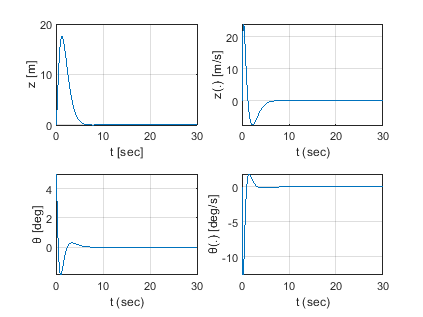

t = 0:0.1:30;

AUG_k = A3 - B3*K3;

sys = ss(AUG_k,eye(4),eye(4),eye(4));
v3 = [0; 0; 5; 0];
y = initial(sys,v3,t);

y1 = [1 0 0 0]*y';
y2 = [0 1 0 0]*y';
y3 = [0 0 1 0]*y';
y4 = [0 0 0 1]*y';

plot(t,y1)
hold on
plot(t,y2)
hold on
plot(t,y3)
hold on
plot(t,y4)
hold off
title('y (States) v/s t')
xlabel('t (sec)')
ylabel('y')
legend('z','z(.)','θ','θ(.)')

subplot(2,2,1); plot(t,y1); grid
xlabel('t [sec]')
ylabel('z [m]')

subplot(2,2,2); plot(t,y2); grid
xlabel('t (sec)')
ylabel('z(.) [m/s]')

subplot(2,2,3); plot(t,y3); grid
xlabel('t (sec)')
ylabel('θ [deg]')

subplot(2,2,4); plot(t,y4); grid
xlabel('t (sec)')
ylabel('θ(.) [deg/s]')

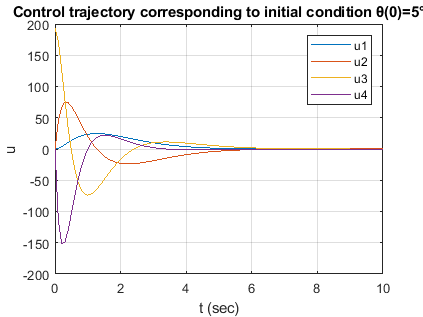



%*** Control trajectory ***
t = 0:0.1:10;

AUG_k = A3 - B3*K3;
sys = ss(AUG_k,eye(4),eye(4),eye(4));
v3 = [0; 0; 5; 0];
y = initial(sys,v3,t);

y1 = [1 0 0 0]*y';
y2 = [0 1 0 0]*y';
y3 = [0 0 1 0]*y';
y4 = [0 0 0 1]*y';

u1 = -K3(1,1)*y1;
u2 = -K3(1,2)*y2;
u3 = -K3(1,3)*y3;
u4 = -K3(1,4)*y4;

subplot(1,1,1); plot(t,u1); grid
hold on
plot(t,u2)
hold on
plot(t,u3)
hold on
plot(t,u4)
hold off
title('Control trajectory corresponding to initial condition θ(0)=5°')
xlabel('t (sec)')
ylabel('u')
legend('u1', 'u2', 'u3', 'u4')